clear;
%Declare symbolic variables
syms r1 r2 r3 v1 v2 v3 q1 q2 q3 omega1 omega2 omega3 beta gamma throttle tau_RW m l g
syms J [1 9]

%Create constants array
consts = [m; l; g];

%Earth-frame radius
r = [r1; r2; r3];
%Earth-frame velocity
v = [v1; v2; v3];

%Quaternion scalar relation formula
q0 = sqrt(1 - q1^2 - q2^2 - q3^2);
%Full quaternion vector
qVec = [q0; q1; q2; q3];
%Chopped Quaternion vector
qChange = [q1; q2; q3];
%Angular velocity (taken wrt E-frame, represented in B-frame)
omegaB = [omega1; omega2; omega3];

%State vector
x = [r; v; qChange; omegaB]

$$x = \left(\begin{array}{c} r_{1}\\ r_{2}\\ r_{3}\\ v_{1}\\ v_{2}\\ v_{3}\\ q_{1}\\ q_{2}\\ q_{3}\\ \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$

%Input vector
u = [beta; gamma; throttle; tau_RW]

$$u = \left(\begin{array}{c} \beta \\ \gamma \\ \mathrm{throttle}\\ \tau_{\mathrm{RW}} \end{array}\right)$$


%Thrust force in terms of throttle input
p1 = -0.000112;
p2 = 0.02072;
p3 = -.268;
F_T = p1*throttle^3 + p2*throttle^2 + p3*throttle;

%Moment of inertia tensor
Jmat = [J1 J2 J3; J4 J5 J6; J7 J8 J9];

%Body-frame thrust vector
TB = F_T * [cos(beta)*cos(gamma); cos(beta)*sin(gamma); -sin(beta)];

%Direction-cosine rotation matrix (Earth to body)
CIB = quatRot(qVec);
%Direction-cosine rotation matrix (Body to earth)
CBI = CIB';

%Derivative of position = v
rdot = v;

%Net force in earth frame
FI = CBI*TB - [m*g; 0; 0];

%Derivative of velocity = acceleration = F / m
vdot = FI / m;

%Quaternion matrix
bigO = [q0 -q3 q2; q3 q0 -q1; -q2 q1 q0];
%Derivative of chopped quaternion array
qdot = simplify(0.5 * bigO * omegaB)

$$qdot = \left(\begin{array}{c} \frac{\omega_{1}\,\sqrt{-{q_{1}}^{2}-{q_{2}}^{2}-{q_{3}}^{2}+1}}{2}-\frac{\omega_{2}\,q_{3}}{2}+\frac{\omega_{3}\,q_{2}}{2}\\ \frac{\omega_{2}\,\sqrt{-{q_{1}}^{2}-{q_{2}}^{2}-{q_{3}}^{2}+1}}{2}+\frac{\omega_{1}\,q_{3}}{2}-\frac{\omega_{3}\,q_{1}}{2}\\ \frac{\omega_{3}\,\sqrt{-{q_{1}}^{2}-{q_{2}}^{2}-{q_{3}}^{2}+1}}{2}-\frac{\omega_{1}\,q_{2}}{2}+\frac{\omega_{2}\,q_{1}}{2} \end{array}\right)$$


%Moment arm between center of mass and thrust point
rTB = [-l; 0; 0];

%Net moment in body frame
MB = zetaCross(rTB)*TB + [tau_RW; 0; 0];

%Derivative of angular velocity
omegaBdot = Jmat \ (MB - zetaCross(omegaB)*Jmat*omegaB);

%Symbolic state derivative
xdot = [rdot; vdot; qdot; omegaBdot]


%Jacobian of state derivative wrt state (Symbolic A matrix)
Jx = jacobian(xdot, x)

%Jacobian of state derivative wrt inputs (Symbolic B matrix)
Ju = jacobian(xdot, u)

mass = 5;
grav = 9.81;
thrustArm = 0.5;
MOI = [0.5543, 2.30E-2,-8.88E-2; 2.30E-2, 0.5518, 0.097345; -8.88E-2, 0.097345	0.042318];

inputLimits = [-pi/12, pi/12; -pi/12, pi/12; 0, 100; -2, 2];

%initial conditions
ri = [10; 10; 0];
vi = [0; 0; 0];
qi = angle2quat(pi/6, 0, 0, 'ZYX')';
qi = qi(2:end); 
omegai = [0; 0; 0];
xi = [ri; vi; qi; omegai];
ui = [0; 0; 0; 0];

%Critical/operating point to linearize around
rcrit = [0; 0; 0];
vcrit = [0; 0; 0];
qcrit = angle2quat(0, 0, 0, 'ZYX')';
qcrit = qcrit(2:end);
omegacrit = [0; 0; 0];
xcrit = [rcrit; vcrit; qcrit; omegacrit];
ucrit = [0; 0; 100; 0];

%Calculate A matrix in state space representation
A = subs(Jx, [x; u; consts], [xcrit; ucrit; [mass; thrustArm; grav]]);
A = double(subs(A, [J1 J2 J3; J4 J5 J6; J7 J8 J9], MOI))

A =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   27.3600         0         0         0
         0         0         0         0         0         0         0  -27.3600         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.5000         0         0
         0         0         0         0         0         0         0         0         0         0    0.5000         0
         0         0        


%Calculate B matrix in state space representation
B = subs(Ju, [x; u; consts], [xcrit; ucrit; [mass; thrustArm; grav]]);
B = double(subs(B, [J1 J2 J3; J4 J5 J6; J7 J8 J9], MOI))

B = 1.0e+03 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0    0.0001         0
         0    0.0137         0         0
   -0.0137         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.1127   -0.6002         0    0.0048


$$G(s) = \left(\begin{array}{cccc} 0 & 0 & \frac{129}{1250\,s^{2}} & 0\\ \frac{197330740925601861}{21990232555520\,s^{4}} & \frac{342}{25\,s^{2}}-\frac{672443571026898621}{13743895347200\,s^{4}} & 0 & \frac{422341395185922723}{1759218604441600\,s^{4}}\\ \frac{1097386092670096251}{439804651110400\,s^{4}}-\frac{342}{25\,s^{2}} & -\frac{197330740925601861}{21990232555520\,s^{4}} & 0 & \frac{1268379889338219651}{28147497671065600\,s^{4}}\\ 0 & 0 & \frac{129}{1250\,s} & 0\\ \frac{197330740925601861}{21990232555520\,s^{3}} & \frac{342}{25\,s}-\frac{672443571026898621}{13743895347200\,s^{3}} & 0 & \frac{422341395185922723}{1759218604441600\,s^{3}}\\ \frac{1097386092670096251}{439804651110400\,s^{3}}-\frac{342}{25\,s} & -\frac{197330740925601861}{21990232555520\,s^{3}} & 0 & \frac{1268379889338219651}{28147497671065600\,s^{3}}\\ \frac{7927374308363873}{140737488355328\,s^{2}} & -\frac{2639633719912017}{8796093022208\,s^{2}} & 0 & \frac{668809641286093}{281474976710656\,s^{2}}\\ -\frac{6417462530234481}{70368744177664\,s^{2}} & \frac{5769904705426955}{17592186044416\,s^{2}} & 0 & -\frac{7417426253439881}{4503599627370496\,s^{2}}\\ \frac{5769904705426955}{17592186044416\,s^{2}} & -\frac{3932418544016951}{2199023255552\,s^{2}} & 0 & \frac{2469832720385513}{281474976710656\,s^{2}}\\ \frac{7927374308363873}{70368744177664\,s} & -\frac{2639633719912017}{4398046511104\,s} & 0 & \frac{668809641286093}{140737488355328\,s}\\ -\frac{6417462530234481}{35184372088832\,s} & \frac{5769904705426955}{8796093022208\,s} & 0 & -\frac{7417426253439881}{2251799813685248\,s}\\ \frac{5769904705426955}{8796093022208\,s} & -\frac{3932418544016951}{1099511627776\,s} & 0 & \frac{2469832720385513}{140737488355328\,s} \end{array}\right)$$

%Maximum allowable states and inputs (for Q and R)
rmax = [5; 1; 1];
vmax = [.5; 1; 1];
qmax = angle2quat(pi/12, pi/12, pi/12, 'ZYX')';
qmax = qmax(2:end);
omegamax = [pi/2; pi/2; pi/2];
xmax = [rmax; vmax; qmax; omegamax];

umax = [pi/12; pi/12; 1000; 1];

%Cost function Q and R matrices
Q = diag(xmax.^-2);
R = diag(umax.^-2);

%Current number of uncontrollable states in A-B system pair
uncontrol = length(A) - rank(ctrb(A, B));

%Optimal control gain matrix K, solution S, and poles P
try
    [K, S, P] = lqr(A, B, Q, R)
catch e
    disp(e.message);
    error("LQR gain generation threw the error above!");
end

K = 1.0e+03 *

   -0.0000    0.0000    0.0003    0.0000   -0.0000    0.0004    0.0000   -0.0043   -0.0002   -0.0000   -0.0004   -0.0000
    0.0000   -0.0003    0.0000    0.0000   -0.0004    0.0000   -0.0000   -0.0002   -0.0036    0.0000   -0.0000   -0.0002
    0.2000    0.0000    0.0000    2.0010    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0090    0.0004   -0.0015    0.0023    0.0001   -0.0004


S =     0.4002    0.0000    0.0000    0.0019   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000    1.4149   -0.0199   -0.0000    0.5016   -0.0285   -0.2607    0.3079    1.4249   -0.0331    0.0360    0.0151
    0.0000   -0.0199    1.4874    0.0000   -0.0290    0.6064   -0.0673   -3.0674   -0.3245   -0.0087   -0.1967   -0.0347
    0.0019   -0.0000    0.0000    0.0194   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.5016   -0.0290   -0.0000    0.6595   -0.0408   -0.4359    0.4193    2.0128   -0.0611    0.0496    0.0234
    0.0000   -0.0285    0.6064    0.0000   -0.0408    0.7905   -0.1122   -4.1764   -0.4362   -0.0159   -0.2683   -0.0467
    0.0000   -0.2607   -0.0673    0.0000   -0.4359   -0.1122   41.6294    1.6289   -6.3445    4.9905    0.2135   -0.7999
   -0.0000    0.3079   -3.0674   -0.0000    0.4193   -4.1764    1.6289   36.5090    3.6972    0.2705    1.9789    0.3201
   -0.0000    1.4249   -0.32

P = 1.0e+02 *

  -0.0010 + 0.0000i
  -0.0104 + 0.0000i
  -0.0107 + 0.0000i
  -0.0208 + 0.0193i
  -0.0208 - 0.0193i
  -0.0315 + 0.0000i
  -0.0399 + 0.0000i
  -0.0581 + 0.0000i
  -0.0731 + 0.0178i
  -0.0731 - 0.0178i


%SIMULATE
fprintf("Starting simulation...\n");

Starting simulation...


tScale = linspace(0, 7.5, 100000);
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
[~, xPlot] = ode45(@(t, x) deriv(t, x, K, [mass; thrustArm; grav], MOI, inputLimits), tScale, xi, opts);
xPlot = xPlot';

%Create simulated control inputs
uPlot = zeros(size(umax, 1), size(tScale, 1));
for i = 1:size(xPlot, 2)
    uPlot(:, i) = constrain(-K*xPlot(:, i), inputLimits);
end
fprintf("Finished Simulation! Displaying Results Below:\n");

Finished Simulation! Displaying Results Below:


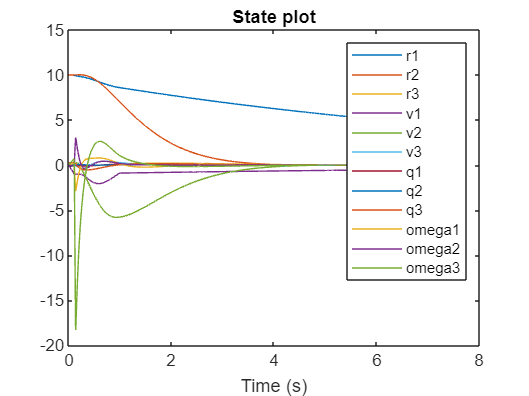

%plot all states over time
figure;
plot(tScale, xPlot)
title("State plot");
xlabel("Time (s)");
legend("r1", "r2", "r3", "v1", "v2", "v3", "q1", "q2", "q3", "omega1", "omega2", "omega3");

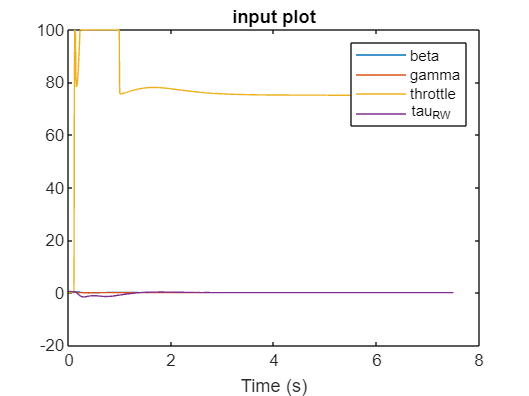

%Plot inputs over time
figure;
plot(tScale, uPlot)
title("input plot");
xlabel("Time (s)");
legend("beta", "gamma", "throttle", "tau_RW");

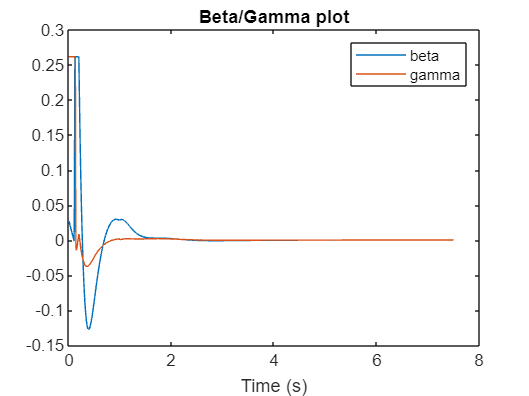

%Plot thrust angles over time
figure;
plot(tScale, uPlot(1:2, :));
title("Beta/Gamma plot");
xlabel("Time (s)");
legend("beta", "gamma");

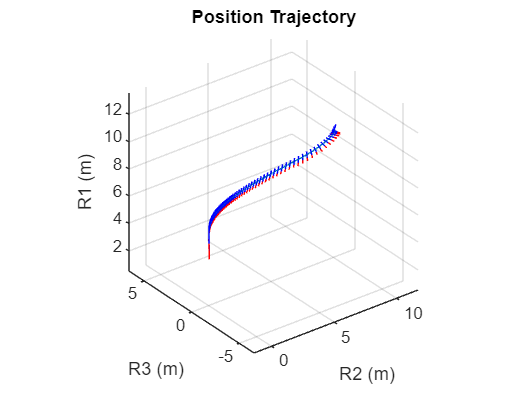

%The following section is for the cool 3-D plot
figure;
rTraj = xPlot(1:3, :);
rocketBody = zeros(6, length(tScale));
TVec = zeros(3, length(tScale));
scaleFactor = .5;
maxThrust = max(uPlot(3, :));

for i = 1:length(tScale)
    rCurrent = rTraj(:, i);
    qshort = xPlot(7:9, i);
    q0C = sqrt(1 - qshort(1)^2 - qshort(2)^2 - qshort(3)^2);
    qCurrent = [q0C; qshort];
    CBICurrent = quatRot(qCurrent)';
    betaCurrent = uPlot(1, i);
    gammaCurrent = uPlot(2, i);
    F_TCurrent = .5*scaleFactor*uPlot(3, i)/maxThrust;
    TBCurrent = F_TCurrent * [cos(betaCurrent)*cos(gammaCurrent); cos(betaCurrent)*sin(gammaCurrent); -sin(betaCurrent)];
    rocketBody(1:3, i) = rCurrent + CBICurrent*[thrustArm*scaleFactor; 0; 0];
    rocketBody(4:6, i) = rCurrent + CBICurrent*[-thrustArm*scaleFactor; 0; 0];
    TVec(:, i) = rCurrent + CBICurrent*([-thrustArm*scaleFactor; 0; 0] - TBCurrent);
end
plot3(rTraj(2, :), rTraj(3, :), rTraj(1, :));
hold on;
numSkip = 750;
for i = 1:numSkip:length(tScale)
    plot3([rocketBody(2, i); rocketBody(5, i)], [rocketBody(3, i); rocketBody(6, i)], [rocketBody(1, i); rocketBody(4, i)], 'b-');
    plot3([rocketBody(5, i); TVec(2, i)], [rocketBody(6, i); TVec(3, i)], [rocketBody(4, i); TVec(1, i)], 'r-');
end

title("Position Trajectory");
xlabel("R2 (m)");
ylabel("R3 (m)");
zlabel("R1 (m)");
axis square
grid on;

xMin = min([rocketBody(2, :); rocketBody(5, :); TVec(2, :)], [], 'all');
xMax = max([rocketBody(2, :); rocketBody(5, :); TVec(2, :)], [], 'all');
yMin = min([rocketBody(3, :); rocketBody(6, :); TVec(3, :)], [], 'all');
yMax = max([rocketBody(3, :); rocketBody(6, :); TVec(3, :)], [], 'all');
zMin = min([rocketBody(1, :); rocketBody(4, :); TVec(1, :)], [], 'all');
zMax = max([rocketBody(1, :); rocketBody(4, :); TVec(1, :)], [], 'all');

xRange = xMax - xMin;
yRange = yMax - yMin;
zRange = zMax - zMin;
xMid = (xMax + xMin) / 2;
yMid = (yMax + yMin) / 2;
zMid = (zMax + zMin) / 2;
plotRange = max([xRange, yRange, zRange]);

axis([xMid - 5*plotRange/8, xMid + 5*plotRange/8, yMid - 5*plotRange/8, yMid + 5*plotRange/8, zMid - 5*plotRange/8, zMid + 5*plotRange/8]);

function CIB = quatRot(q)
    q0 = q(1);
    q1 = q(2);
    q2 = q(3);
    q3 = q(4);
    CIB = [1-2*(q2^2 + q3^2), 2*(q1*q2 + q0*q3), 2*(q1*q3 - q0*q2);
        2*(q1*q2 - q0*q3), 1-2*(q1^2 + q3^2), 2*(q2*q3 + q0*q1);
        2*(q1*q3 + q0*q2), 2*(q2*q3 - q0*q1), 1-2*(q1^2 + q2^2)];
end

function zc = zetaCross(zeta)
    zc = [0 -zeta(3) zeta(2); zeta(3) 0 -zeta(1); -zeta(2) zeta(1) 0];
end

function xdot = deriv(~, x, K, consts, MOI, limits)
    m = consts(1);
    l = consts(2);
    g = consts(3);
    J1 = MOI(1, 1);
    J2 = MOI(1, 2);
    J3 = MOI(1, 3);
    J4 = MOI(2, 1);
    J5 = MOI(2, 2);
    J6 = MOI(2, 3);
    J7 = MOI(3, 1);
    J8 = MOI(3, 2);
    J9 = MOI(3, 3);
    v1 = x(4);
    v2 = x(5);
    v3 = x(6);
    q1 = x(7);
    q2 = x(8);
    q3 = x(9);
    omega1 = x(10);
    omega2 = x(11);
    omega3 = x(12);

    u = constrain(-K * x, limits);
    beta = u(1);
    gamma = u(2);
    throttle = u(3);
    tau_RW = u(4);

    xdot = [v1; v2; v3; -(g*m - sin(beta)*(2*q1*q3 + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*q2)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250) - cos(beta)*cos(gamma)*(2*(q2)^2 + 2*(q3)^2 - 1)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250) + cos(beta)*sin(gamma)*(2*q1*q2 - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*q3)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250))/m; (sin(beta)*(2*q2*q3 - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*q1)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250) + cos(beta)*sin(gamma)*(2*(q1)^2 + 2*(q3)^2 - 1)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250) - cos(beta)*cos(gamma)*(2*q1*q2 + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*q3)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250))/m; -(sin(beta)*(2*(q1)^2 + 2*(q2)^2 - 1)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250) + cos(beta)*cos(gamma)*(2*q1*q3 - 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*q2)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250) + cos(beta)*sin(gamma)*(2*q2*q3 + 2*conj(sqrt(- q1^2 - q2^2 - q3^2 + 1))*q1)*((7*throttle^3)/62500 - (259*throttle^2)/12500 + (67*throttle)/250))/m; (omega1*sqrt(- q1^2 - q2^2 - q3^2 + 1))/2 - (omega2*q3)/2 + (omega3*q2)/2; (omega2*sqrt(- q1^2 - q2^2 - q3^2 + 1))/2 + (omega1*q3)/2 - (omega3*q1)/2; (omega3*sqrt(- q1^2 - q2^2 - q3^2 + 1))/2 - (omega1*q2)/2 + (omega2*q1)/2; (62500*J2^2*J6*omega2^2 + 62500*J2^2*J9*omega2*omega3 - 62500*J2*J3*J5*omega2^2 + 62500*J2*J3*J6*omega2*omega3 - 62500*J2*J3*J8*omega2*omega3 + 62500*J2*J3*J9*omega3^2 - 62500*J2*J5*J6*omega1*omega2 - 62500*J2*J6^2*omega1*omega3 - 62500*J4*J2*J6*omega1^2 + 62500*J1*J2*J6*omega1*omega2 + 7*l*cos(beta)*sin(gamma)*J2*J6*throttle^3 - 1295*l*cos(beta)*sin(gamma)*J2*J6*throttle^2 + 16750*l*cos(beta)*sin(gamma)*J2*J6*throttle - 62500*J2*J8*J9*omega1*omega2 - 62500*J2*J9^2*omega1*omega3 - 62500*J7*J2*J9*omega1^2 + 62500*J1*J2*J9*omega1*omega3 - 7*l*sin(beta)*J2*J9*throttle^3 + 1295*l*sin(beta)*J2*J9*throttle^2 - 16750*l*sin(beta)*J2*J9*throttle - 62500*J3^2*J5*omega2*omega3 - 62500*J3^2*J8*omega3^2 + 62500*J3*J5^2*omega1*omega2 + 62500*J3*J5*J6*omega1*omega3 + 62500*J4*J3*J5*omega1^2 - 62500*J1*J3*J5*omega1*omega2 - 7*l*cos(beta)*sin(gamma)*J3*J5*throttle^3 + 1295*l*cos(beta)*sin(gamma)*J3*J5*throttle^2 - 16750*l*cos(beta)*sin(gamma)*J3*J5*throttle + 62500*J3*J8^2*omega1*omega2 + 62500*J3*J8*J9*omega1*omega3 + 62500*J7*J3*J8*omega1^2 - 62500*J1*J3*J8*omega1*omega3 + 7*l*sin(beta)*J3*J8*throttle^3 - 1295*l*sin(beta)*J3*J8*throttle^2 + 16750*l*sin(beta)*J3*J8*throttle + 62500*J5^2*J9*omega2*omega3 - 62500*J5*J6*J8*omega2*omega3 + 62500*J5*J6*J9*omega3^2 - 62500*J5*J8*J9*omega2^2 - 62500*J5*J9^2*omega2*omega3 - 62500*J7*J5*J9*omega1*omega2 + 62500*J4*J5*J9*omega1*omega3 + 62500*tau_RW*J5*J9 - 62500*J6^2*J8*omega3^2 + 62500*J6*J8^2*omega2^2 + 62500*J6*J8*J9*omega2*omega3 + 62500*J7*J6*J8*omega1*omega2 - 62500*J4*J6*J8*omega1*omega3 - 62500*tau_RW*J6*J8)/(62500*(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7)); -(62500*J1^2*J6*omega1*omega2 + 62500*J1^2*J9*omega1*omega3 - 62500*J1*J3*J4*omega1*omega2 + 62500*J1*J3*J6*omega2*omega3 - 62500*J1*J3*J7*omega1*omega3 + 62500*J1*J3*J9*omega3^2 - 62500*J1*J4*J6*omega1^2 - 62500*J1*J6^2*omega1*omega3 - 62500*J5*J1*J6*omega1*omega2 + 62500*J2*J1*J6*omega2^2 + 7*l*cos(beta)*sin(gamma)*J1*J6*throttle^3 - 1295*l*cos(beta)*sin(gamma)*J1*J6*throttle^2 + 16750*l*cos(beta)*sin(gamma)*J1*J6*throttle - 62500*J1*J7*J9*omega1^2 - 62500*J1*J9^2*omega1*omega3 - 62500*J8*J1*J9*omega1*omega2 + 62500*J2*J1*J9*omega2*omega3 - 7*l*sin(beta)*J1*J9*throttle^3 + 1295*l*sin(beta)*J1*J9*throttle^2 - 16750*l*sin(beta)*J1*J9*throttle - 62500*J3^2*J4*omega2*omega3 - 62500*J3^2*J7*omega3^2 + 62500*J3*J4^2*omega1^2 + 62500*J3*J4*J6*omega1*omega3 + 62500*J5*J3*J4*omega1*omega2 - 62500*J2*J3*J4*omega2^2 - 7*l*cos(beta)*sin(gamma)*J3*J4*throttle^3 + 1295*l*cos(beta)*sin(gamma)*J3*J4*throttle^2 - 16750*l*cos(beta)*sin(gamma)*J3*J4*throttle + 62500*J3*J7^2*omega1^2 + 62500*J3*J7*J9*omega1*omega3 + 62500*J8*J3*J7*omega1*omega2 - 62500*J2*J3*J7*omega2*omega3 + 7*l*sin(beta)*J3*J7*throttle^3 - 1295*l*sin(beta)*J3*J7*throttle^2 + 16750*l*sin(beta)*J3*J7*throttle + 62500*J4^2*J9*omega1*omega3 - 62500*J4*J6*J7*omega1*omega3 + 62500*J4*J6*J9*omega3^2 - 62500*J4*J7*J9*omega1*omega2 - 62500*J4*J9^2*omega2*omega3 - 62500*J8*J4*J9*omega2^2 + 62500*J5*J4*J9*omega2*omega3 + 62500*tau_RW*J4*J9 - 62500*J6^2*J7*omega3^2 + 62500*J6*J7^2*omega1*omega2 + 62500*J6*J7*J9*omega2*omega3 + 62500*J8*J6*J7*omega2^2 - 62500*J5*J6*J7*omega2*omega3 - 62500*tau_RW*J6*J7)/(62500*(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7)); (62500*J1^2*J5*omega1*omega2 + 62500*J1^2*J8*omega1*omega3 - 62500*J1*J2*J4*omega1*omega2 + 62500*J1*J2*J5*omega2^2 - 62500*J1*J2*J7*omega1*omega3 + 62500*J1*J2*J8*omega2*omega3 - 62500*J1*J4*J5*omega1^2 - 62500*J1*J5^2*omega1*omega2 - 62500*J6*J1*J5*omega1*omega3 + 62500*J3*J1*J5*omega2*omega3 + 7*l*cos(beta)*sin(gamma)*J1*J5*throttle^3 - 1295*l*cos(beta)*sin(gamma)*J1*J5*throttle^2 + 16750*l*cos(beta)*sin(gamma)*J1*J5*throttle - 62500*J1*J7*J8*omega1^2 - 62500*J1*J8^2*omega1*omega2 - 62500*J9*J1*J8*omega1*omega3 + 62500*J3*J1*J8*omega3^2 - 7*l*sin(beta)*J1*J8*throttle^3 + 1295*l*sin(beta)*J1*J8*throttle^2 - 16750*l*sin(beta)*J1*J8*throttle - 62500*J2^2*J4*omega2^2 - 62500*J2^2*J7*omega2*omega3 + 62500*J2*J4^2*omega1^2 + 62500*J2*J4*J5*omega1*omega2 + 62500*J6*J2*J4*omega1*omega3 - 62500*J3*J2*J4*omega2*omega3 - 7*l*cos(beta)*sin(gamma)*J2*J4*throttle^3 + 1295*l*cos(beta)*sin(gamma)*J2*J4*throttle^2 - 16750*l*cos(beta)*sin(gamma)*J2*J4*throttle + 62500*J2*J7^2*omega1^2 + 62500*J2*J7*J8*omega1*omega2 + 62500*J9*J2*J7*omega1*omega3 - 62500*J3*J2*J7*omega3^2 + 7*l*sin(beta)*J2*J7*throttle^3 - 1295*l*sin(beta)*J2*J7*throttle^2 + 16750*l*sin(beta)*J2*J7*throttle + 62500*J4^2*J8*omega1*omega3 - 62500*J4*J5*J7*omega1*omega3 + 62500*J4*J5*J8*omega2*omega3 - 62500*J4*J7*J8*omega1*omega2 - 62500*J4*J8^2*omega2^2 - 62500*J9*J4*J8*omega2*omega3 + 62500*J6*J4*J8*omega3^2 + 62500*tau_RW*J4*J8 - 62500*J5^2*J7*omega2*omega3 + 62500*J5*J7^2*omega1*omega2 + 62500*J5*J7*J8*omega2^2 + 62500*J9*J5*J7*omega2*omega3 - 62500*J6*J5*J7*omega3^2 - 62500*tau_RW*J5*J7)/(62500*(J1*J5*J9 - J1*J6*J8 - J2*J4*J9 + J2*J6*J7 + J3*J4*J8 - J3*J5*J7))];
end

function unew = constrain(u, limits)
    unew = zeros(size(u, 1), size(u, 2));
    
    beta_min = limits(1, 1);
    beta_max = limits(1, 2);
    if u(1) > beta_max
        unew(1) = beta_max;
    elseif u(1) < beta_min
        unew(1) = beta_min;
    else
        unew(1) = u(1);
    end
    
    gamma_min = limits(2, 1);
    gamma_max = limits(2, 2);
    if u(2) > gamma_max
        unew(2) = gamma_max;
    elseif u(2) < gamma_min
        unew(2) = gamma_min;
    else
        unew(2) = u(2);
    end

    T_min = limits(3, 1);
    T_max = limits(3, 2);

    if u(3) > T_max
        unew(3) = T_max;
    elseif u(3) < T_min
        unew(3) = T_min;
    else
        unew(3) = u(3);
    end
    
    tau_min = limits(4, 1);
    tau_max = limits(4, 2);
    if u(4) > tau_max
        unew(4) = tau_max;
    elseif u(4) < tau_min
        unew(4) = tau_min;
    else
        unew(4) = u(4);
    end
end